#  Visualise parallel and meridians over the catheter points (not over the mesh).

Note This live script comments the functionality from the script **VISUALISEPARALLELANDMERIDIANSOVERTHEPOINTSV2.m**

4th  May 2017

Set up the analysis

% Path to CARTO file
dataSubFolder = 'RyC_Patient 2016_12_20';
dataFile      = 'ECG.mat';
cartoFile     = fullfile(getDataFolder(), dataSubFolder, dataFile);

% And analyse (BIP)OLAR or (MON)OPOLAR
currentType  = 'BIP';

% Enable below to manually pick a point
enableInteraction = true;

% xcorr analysis
maximumLag = 400;

% set the sampling frequency here
samplingFreq = 1e3;

matchingFNames = which(cartoFile);
if isempty(matchingFNames)
  errordlg('Can''t resolve path to file. Run initialise()');
  return;
end
fullPath2CartoFile  = matchingFNames;
[~, srcDataName, ~] = fileparts(cartoFile);

% load loadRamonyCajalData (same interface for loadSimulation/loadCartoXPData)
[data, pointsInfo, meshData, cartoData, cathererData] = ...
  loadRamonyCajalData(fullPath2CartoFile);

cathererTable = struct2table(cathererData);

idxType        = strcmpi(cathererTable{:, 'type'}, currentType);
cathererTable  = cathererTable(idxType, :);
pointsPosition = cathererTable{:, {'x', 'y', 'z'}};
textPosition   = pointsPositionAsText(pointsPosition);

Once the data is loaded, we can still do some  aditional filtering. ie: only the electrode '20A_1_2'

idxElectrode   = ismember(cathererTable{:, 'pentaRayElectrode'}, '20A_1_2');

cathererTable  = cathererTable(idxElectrode, :);

In the following cell, compute a descriptor over the current points:

% Get the Botteron frequency
bottBandWidth = 2;
[botFrequencies, organisationIdx] = getBotteronAndOI(cathererTable{:, 'signal'}, ...
  samplingFreq, bottBandWidth);

1000/4958 processed...
2000/4958 processed...
3000/4958 processed...
4000/4958 processed...


Plot the descriptor. The code below will map the descriptor into the mesh provided by Carto and plot it on the half left side of the first monitor. The second bit of code will plot the actual points and wait until the user selects one of them.

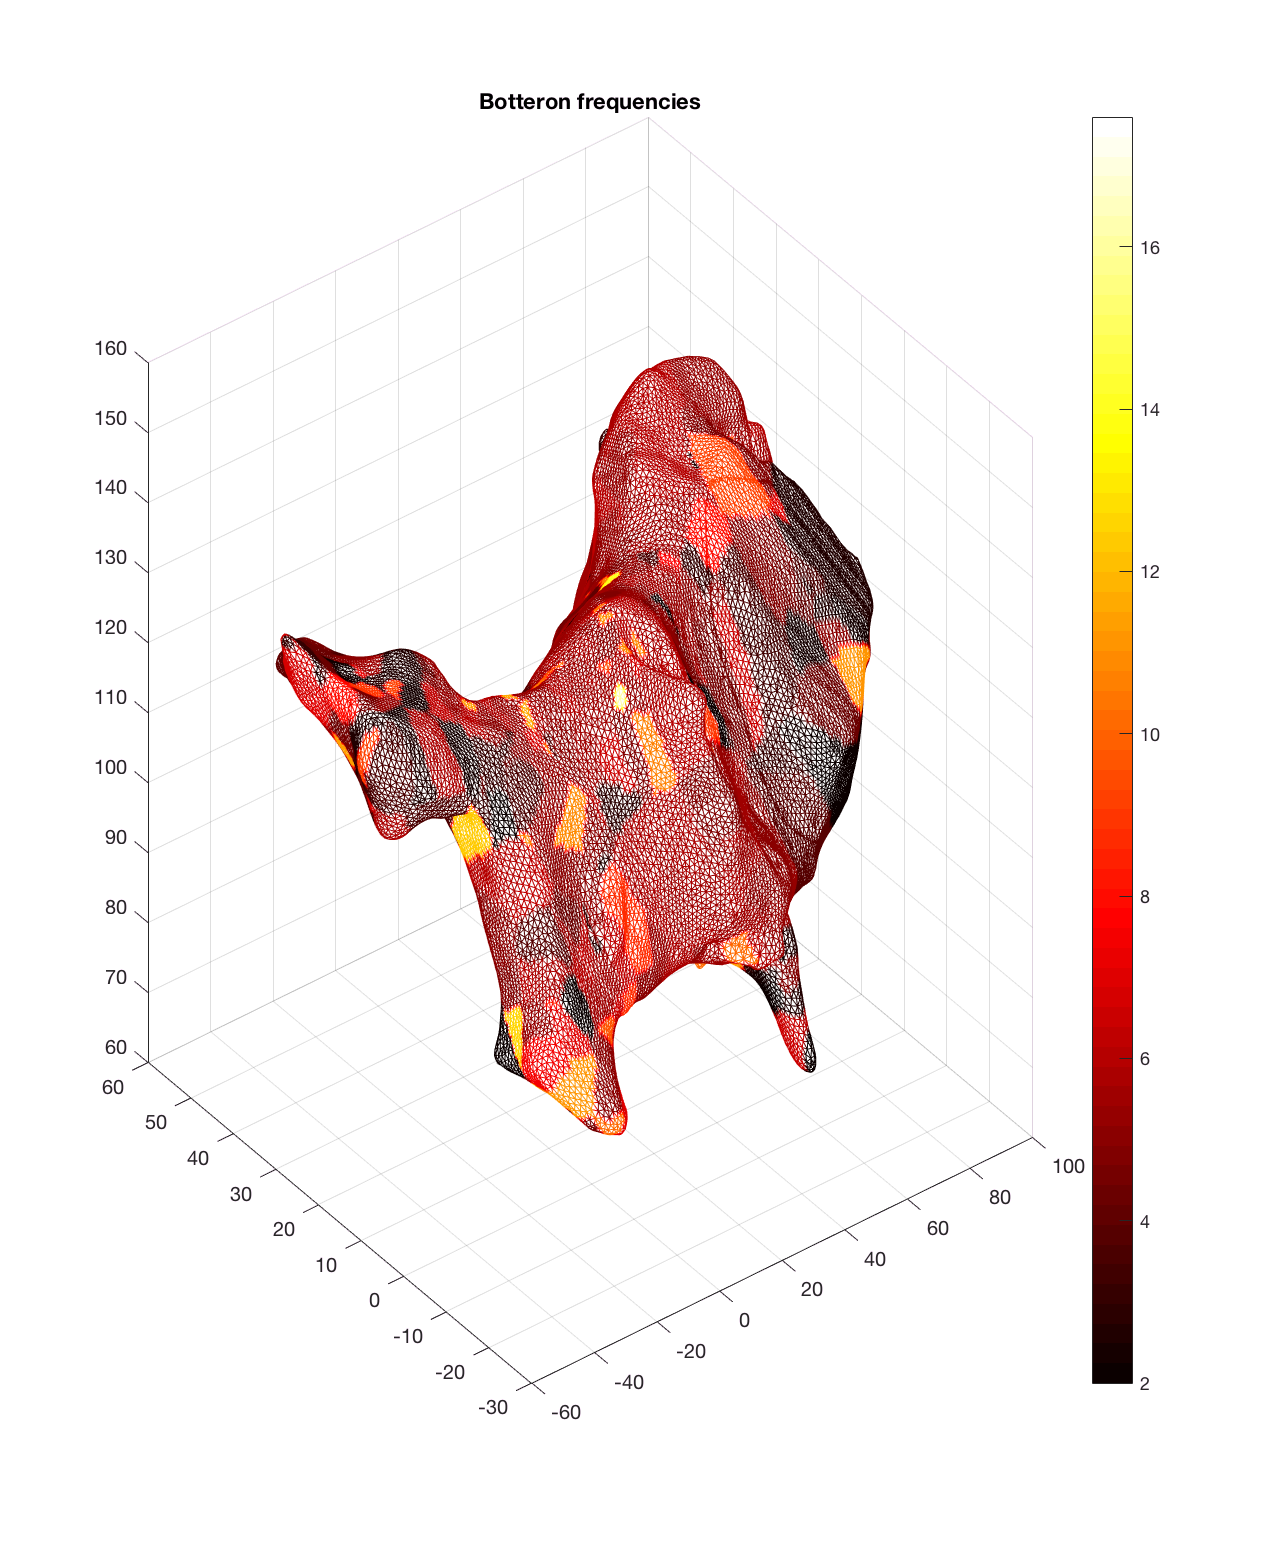

%% Plot the descriptor

pointDescriptor = botFrequencies;
figTitle        = 'Botteron frequencies';

% The function PLOTDESCRIPTOROVERMESHV2 plots the descriptor and maps the
% points to the current mesh.
plotDescriptorOverMeshV2(meshData, cathererTable, ...
  pointDescriptor, figTitle);


% The function PLOTDESCRIPTOROVERPOINTSINTERACTION plots the given
% descriptor over the actual acquisition points and waits until the user
% selects a point to calculate the parallel/meridians.
if enableInteraction
  selectedPointIdx = ...
    plotDescriptorOverPointsInteraction(cathererTable, ...
    pointDescriptor, figTitle);
else
  plotDescriptorOverPoints(cathererTable, pointDescriptor, figTitle); %#ok<UNRCH>
end

Plotting 500/4958...
Plotting 1000/4958...
Plotting 1500/4958...
Plotting 2000/4958...
Plotting 2500/4958...
Plotting 3000/4958...
Plotting 3500/4958...
Plotting 4000/4958...
Plotting 4500/4958...


% Calculate the parallels and meridians
[parallelPath, meridianPath, pathInfo] = ...
  getMeridianAndParallel(selectedPointIdx, pointsPosition);


...Switching off mesh viz


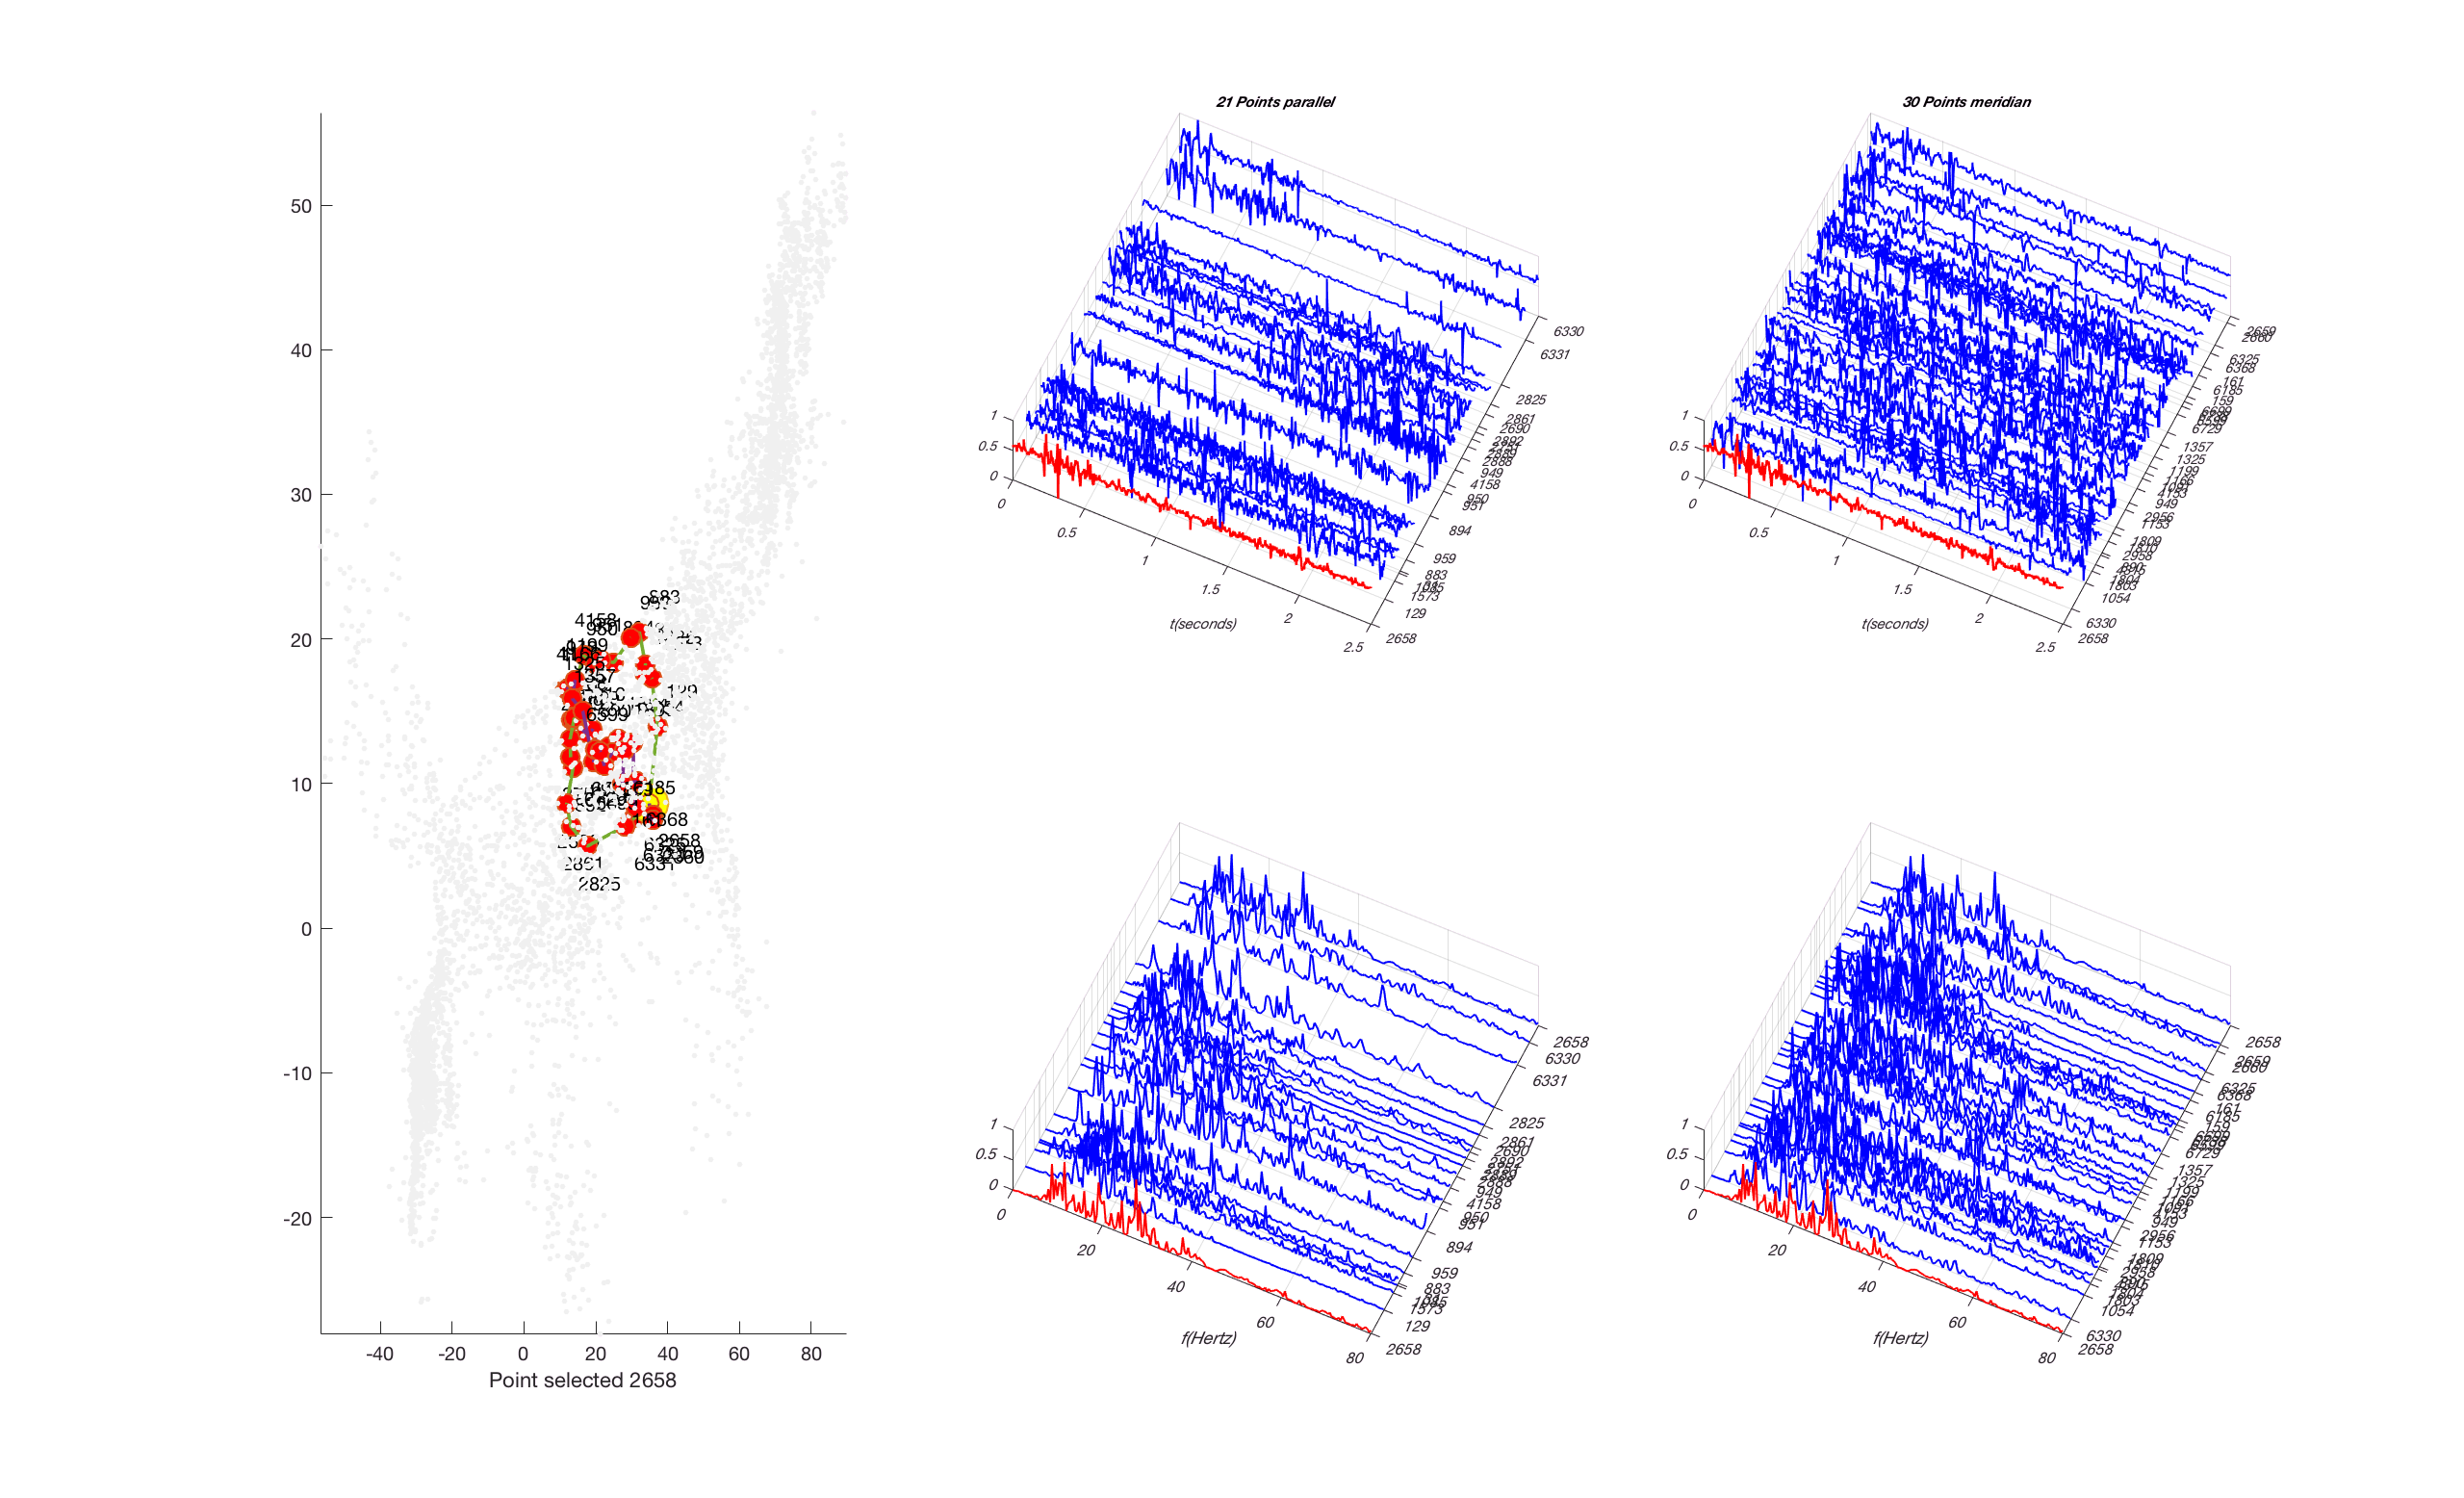

% Plot the meridian and parallels
doPlotMesh = false;

plotDataAnalysisParallelAndMeridianV4(cathererTable, doPlotMesh, meshData, ...
  selectedPointIdx, textPosition, parallelPath, meridianPath, pathInfo);

This section deals with the autocorrelation of the signals found across the meridian and parallel paths

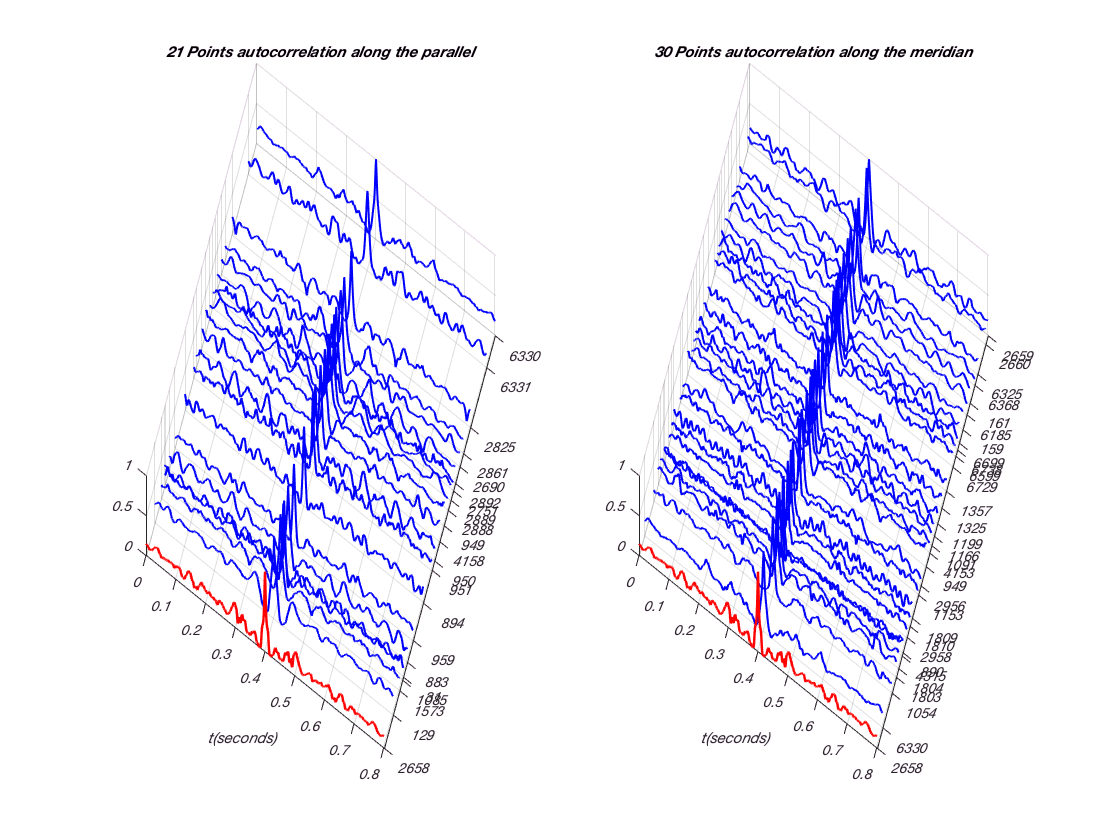

% xcorr over the parallel
f    = figure();
hAxL = subplot(1,2,1);
hAxR = subplot(1,2,2);

% get the closed path
idxClosedPath = [parallelPath(1).idxPointA, parallelPath.idxPointB];

% get the signals bounded to the path
parallelBulkData = cathererTable{idxClosedPath, 'signal'};
parallelsData    = getXCorr(parallelBulkData, maximumLag);

numSamples  = size(parallelsData, 2);
timeLength  = numSamples/samplingFreq;

doScaling  = true;
pathType   = 'autocorrelation along the parallel';
pointsList = cathererTable.pointsId(pathInfo.allParallelPointsIdx);

plotSignalsIn3D(hAxL, timeLength, numSamples, ...
  parallelsData, pathType, parallelPath, pointsList, doScaling);

% xcorr over the meridian
% get the closed path
idxClosedPath = [meridianPath(1).idxPointA, meridianPath.idxPointB];

% get the signals bounded to the path
meridianBulkData = cathererTable{idxClosedPath, 'signal'};
meridiansData    = getXCorr(meridianBulkData, maximumLag);

numSamples  = size(meridiansData, 2);
timeLength  = numSamples/samplingFreq;

doScaling   = true;
pathType    = 'autocorrelation along the meridian';
pointsList  = cathererTable.pointsId(pathInfo.allMeridianPointsIdx);

plotSignalsIn3D(hAxR, timeLength, numSamples, ...
  meridiansData, pathType, meridianPath, pointsList, doScaling);

In this section, we will plot the Botteron signals across the meridians and parallels.

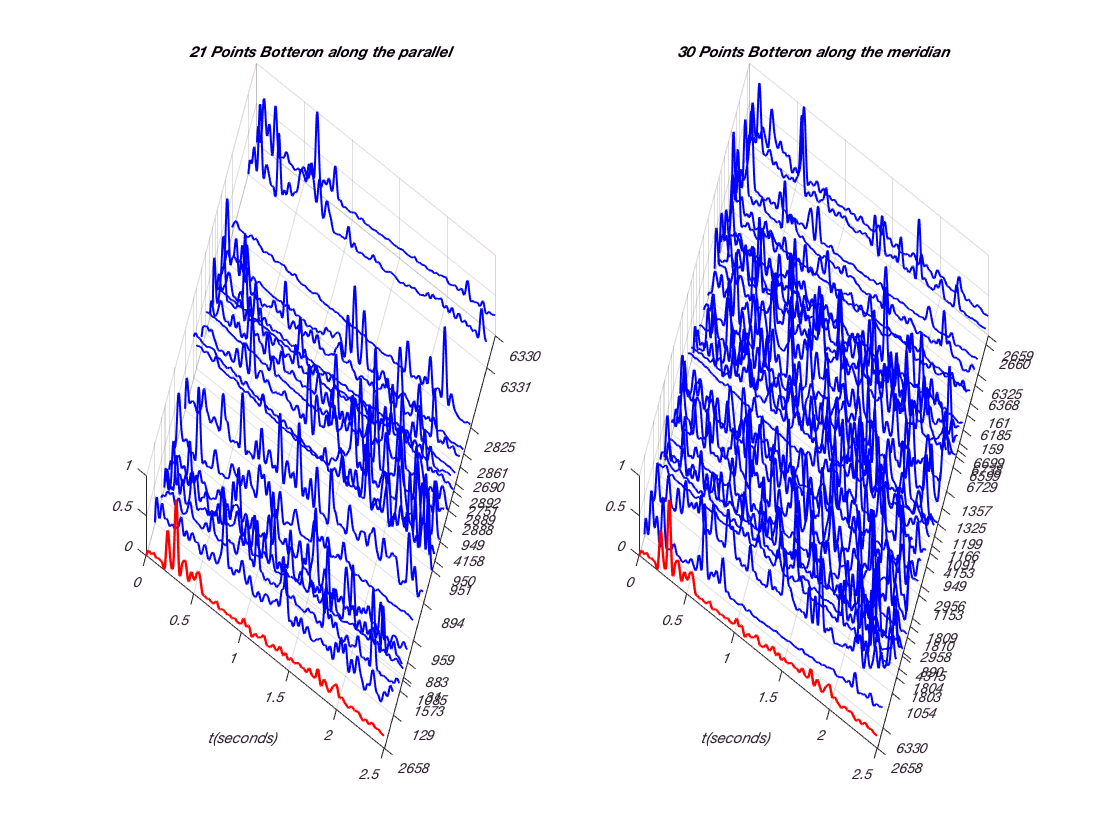

% Parallel
[parallelsBott, parallelsBotFreqs] = ...
  getBotteronSignals(parallelBulkData, samplingFreq);

f2    = figure();
h2AxL = subplot(1,2,1);
h2AxR = subplot(1,2,2);

numSamples = size(parallelsBott, 2);
timeLength = numSamples/samplingFreq;

doScaling  = true;
pathType   = 'Botteron along the parallel';
pointsList = cathererTable.pointsId(pathInfo.allParallelPointsIdx);

plotSignalsIn3D(h2AxL, timeLength, numSamples, ...
  parallelsBott, pathType, parallelPath, pointsList, doScaling);


% Meridian
[meridiansBott, meridiansBotFreqs] = ...
  getBotteronSignals(meridianBulkData, samplingFreq);

numSamples = size(meridiansBott, 2);
timeLength = numSamples/samplingFreq;

doScaling  = true;
pathType   = 'Botteron along the meridian';
pointsList = cathererTable.pointsId(pathInfo.allMeridianPointsIdx);
  
plotSignalsIn3D(h2AxR, timeLength, numSamples, ...
  meridiansBott, pathType, meridianPath, pointsList, doScaling);

On a side note

Plot the catheter grouping the branches by colour.

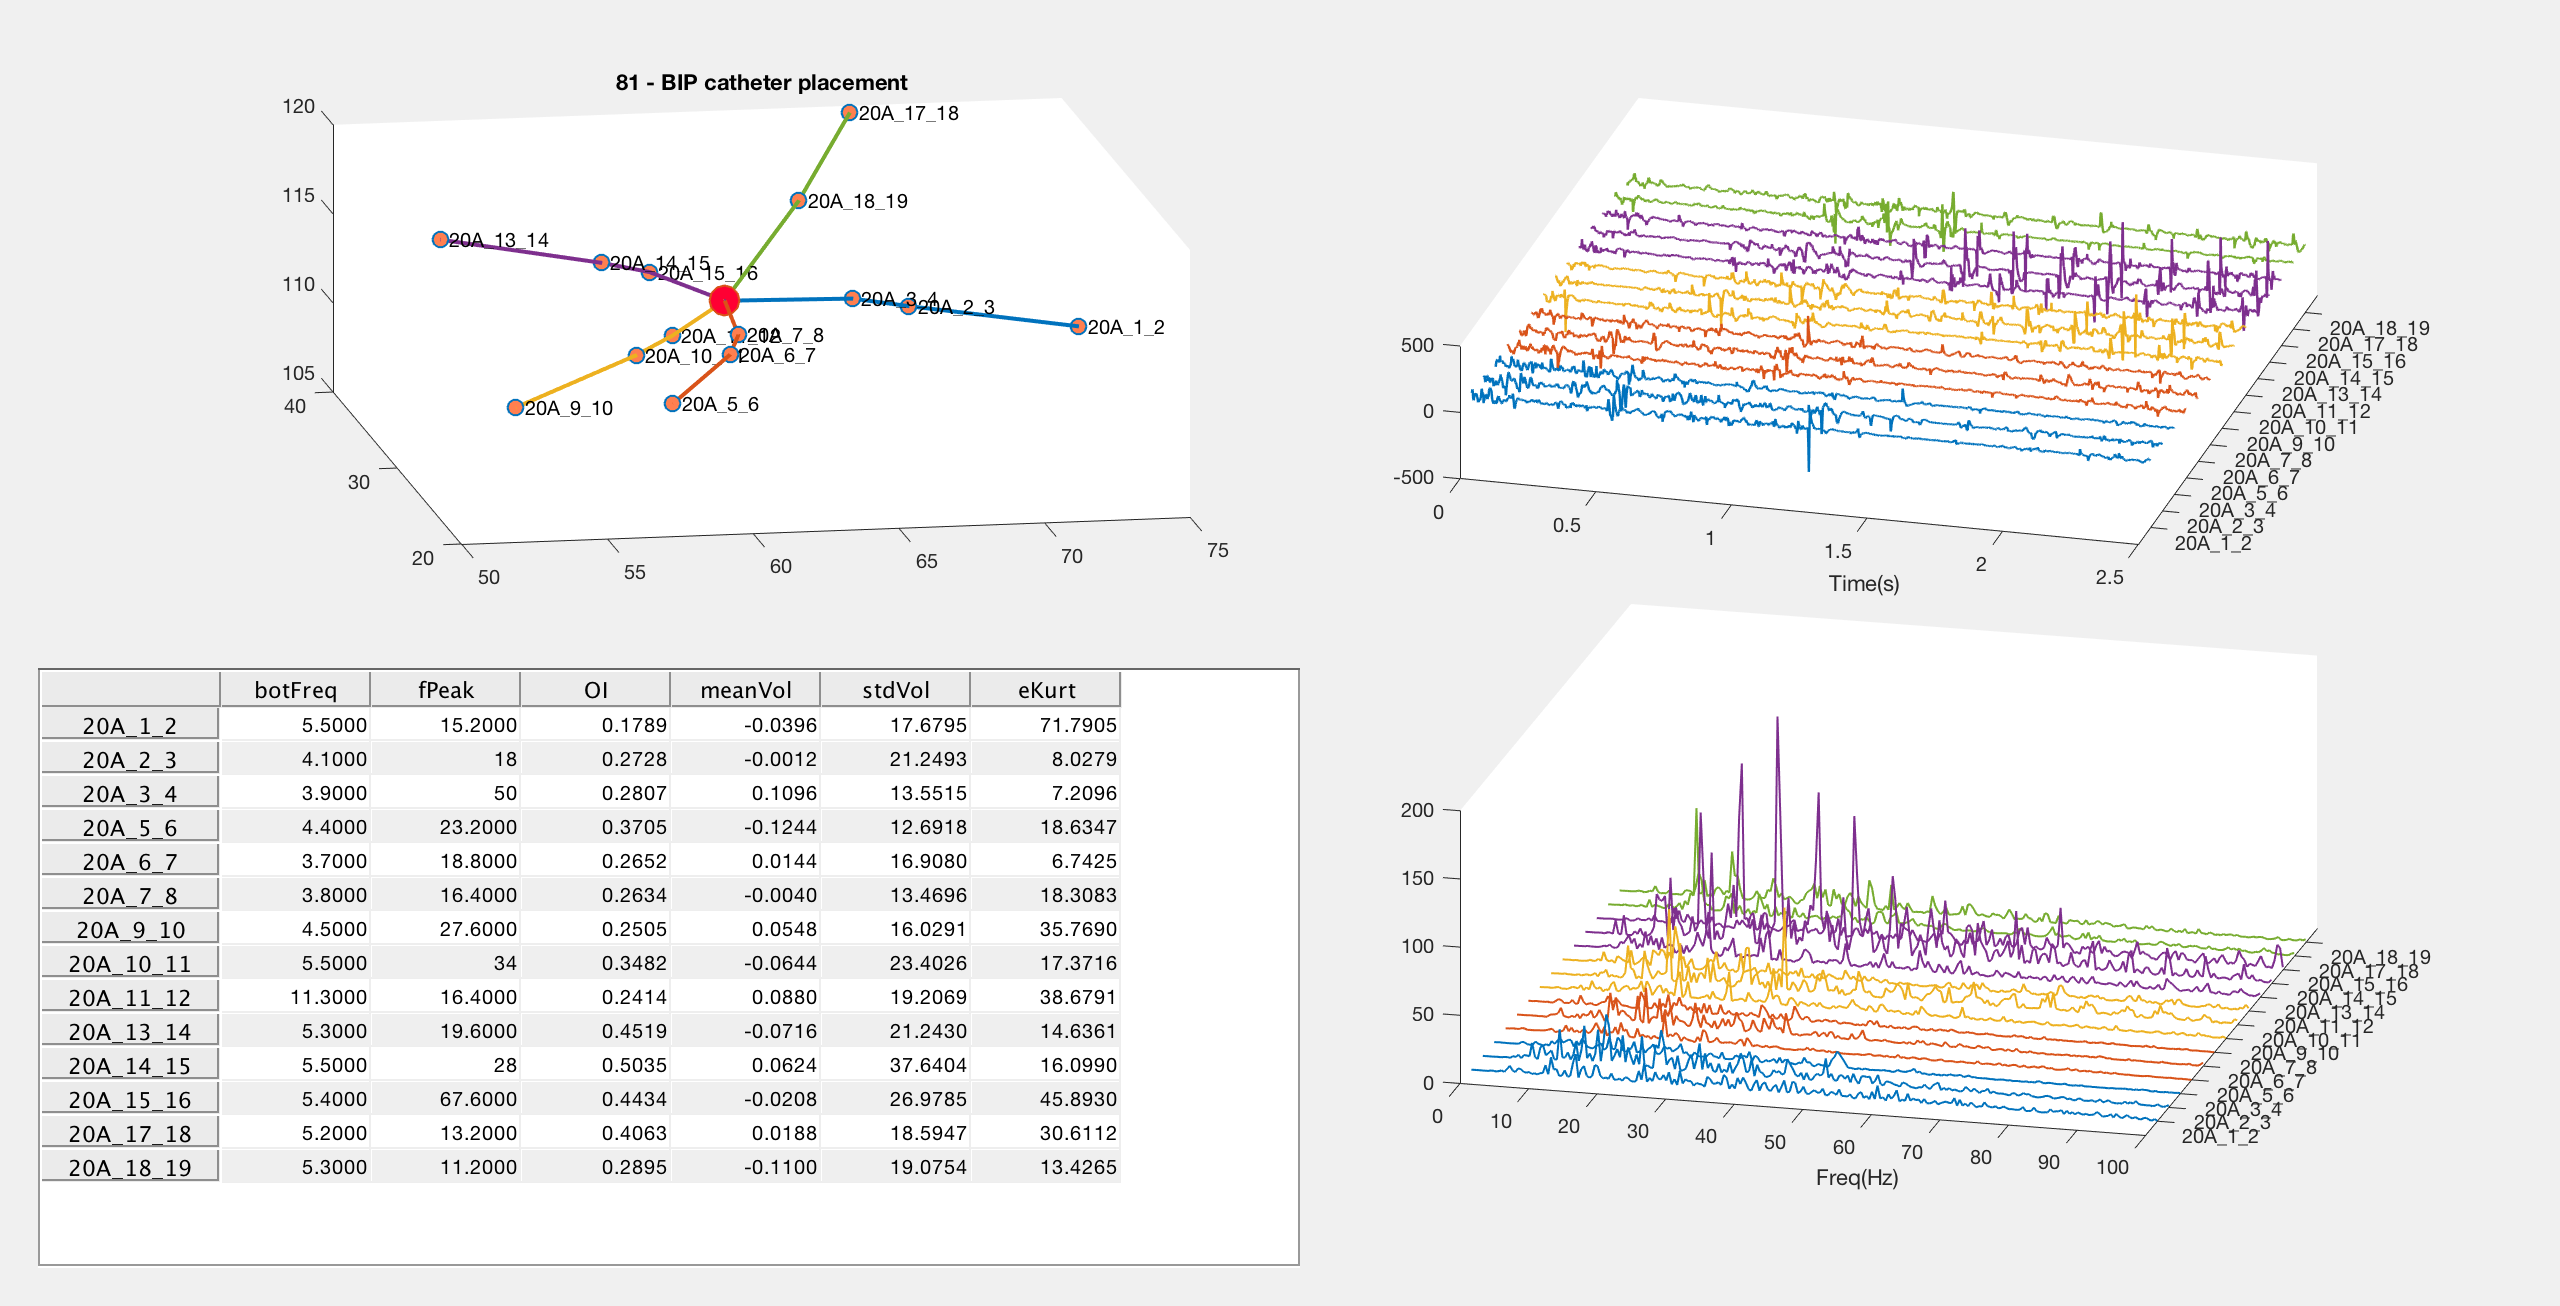

% Get a list of the points recorded with the catherer
listOfPoints = unique(cathererTable{:, 'pentaRayPoint'});
% select a random one
currentPoint = listOfPoints(9);
% plot the catheter
plotCatheterSignalsFrequencyV2(cathererTable, currentPoint, currentType);